# Mobile robot short Project

Given the kown workspace: Sensors_Data.mat, and  Enviroment.png

Answer the following question:

## Pose estimation given encoder data (10%)

Before start:

- Open the Simulink model EKF_Pose_estimation.slx and get familiar with: 'Where2Find_Code.pdf'. 

- Have a look to section See an animation of the file: 3_MR_SP_support.mlx 

Every thing is done, the exercise consist in compile in a mlx file all the concepts.

1.- Implement in this mlx file:

a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose. 

2.- Display in a figure:

a) x,y poses for both trajectories: theoric and estimated 

b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

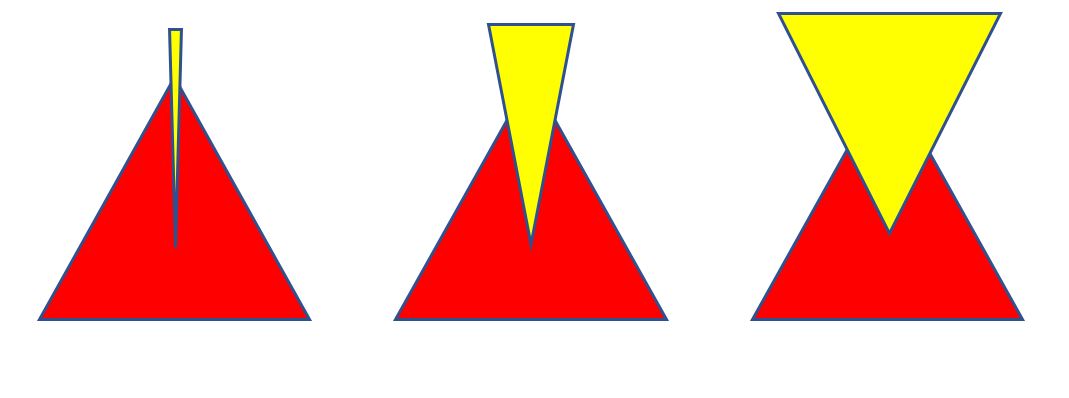

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Record a movie of the robot moving along the corridor displaying both trajectories.

 See: help VideoWriter to get familiar with the matlab functions

clear

clf
load("Encoder_Data.mat")
load("Sensors_Data.mat")
%sim("EKF_Pose_estimation_1.slx");

S = W/2;
t=(0:Ts:Tf-Ts)';
Ratio = 100;

R_v = right_angular_speed;
L_v = left_angular_speed;

R_v(:,2) = R_v(:,2) .* r_w ./ 100;
L_v(:,2) = L_v(:,2) .* r_w ./ 100;

R_inc = R_v;
R_inc(:,2) = R_inc(:,2) .* Ts;

L_inc = L_v;
L_inc(:,2) = L_inc(:,2) .* Ts;

delta_d = (R_inc(:,2)+L_inc(:,2))/2;
delta_t = (R_inc(:,2)-L_inc(:,2))/W;

**a) Pose_theoric, asumme no noise.**

Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2)

Initial_pose =          0    1.0000         0    8.6500
   -1.0000         0         0   17.2000
         0         0    1.0000         0
         0         0         0    1.0000


Pose(:,:,1)=Initial_pose;

 for i=1:length(delta_t)-1
    Pose(:,:,i+1)=Pose(:,:,i)*trotz(delta_t(i))*transl(delta_d(i),0,0);
    Position(:,i+1)=transl(Pose(:,:,i));
    Orientation(:,i+1)=tr2rpy(Pose(:,:,i));
 end

**b) Pose_estimation by adding noise in odometry**

ProcNoiseD=0.019^2; % is a variance. Stdmax<0.02
ProcNoiseTheta=0.003^2 % is a variance. Stdmax <0.0035

ProcNoiseTheta = 9.0000e-06

Ts=0.02

Ts = 0.0200


V = [ ProcNoiseD 0; 0 ProcNoiseTheta];

noiseD = rand*V(1,1);
noiseTheta = rand*V(2,2);

Position_noise(:,1) = zeros(size(Position(:,1)));
Position_noise(:,2) = Position(:,2);

Orientation_n = zeros(3004,1);
Orientation_n(2) = Orientation(3,2);

 for i=3:length(delta_t)
    Position_noise(1,i)=Position_noise(1,i-1) + (delta_d(i)+noiseD)*cos(Orientation_n(i-1));
    Position_noise(2,i)=Position_noise(2,i-1) + (delta_d(i)+noiseD)*sin(Orientation_n(i-1));
    Orientation_n(i)=mod(Orientation_n(i-1) + delta_t(i) + noiseTheta , 2*pi);
 end

**c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose.**

Pk(:,:,1) = eye(3) * 0.001;

for i = 1:(length(t)-1)
    F_x = [1 0 -delta_d(i)*sin(Orientation(i));...
       0 1  delta_d(i)*cos(Orientation(i));...
       0 0 1];
    F_v = [cos(Orientation(i)) 0;....
       sin(Orientation(i)) 0;...
       0 1];
    Pk(:,:,i+1) = F_x*Pk(:,:,i)*F_x' + F_v*[V(1) 0;0 V(2)]*F_v'; 
end

**a) x,y poses for both trajectories: theoric and estimated**

figure
I = imread('Enviroment.png');
x_img = [0 35.9];
y_img = [23.31 0];
image(I, 'XData', x_img, 'YData',y_img);
axis xy
grid on
title('trajectory')
xlabel('X [m]')
ylabel('Y [m]')
hold on

plot(Position(1,2:end), Position(2,2:end), 'b');
plot(Position_noise(1,2:end), Position_noise(2,2:end), 'r');

**b) ellipses representing x,y uncertanty. Do it every 15-20 poses**

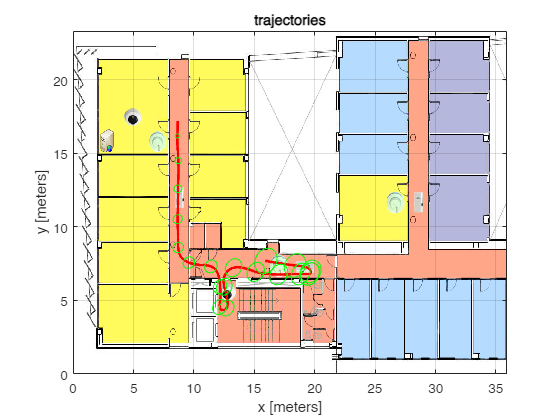

image(I,'XData',x_img,'YData',y_img,"AlphaData",0.75);
axis xy
hold on
    plot( ...
        Position(1,2:end), ...
        Position(2,2:end), ...
        'k', ...
        'Color','r', ...
        "LineWidth",2 ...
    )
    title('trajectories'); xlabel ('x [meters]'); ylabel ('y [meters]')
    for i=1:length(delta_t)
        if (mod(i,150)==0)
            plot_ellipse( ...
                Pk(1:2,1:2,i), ...
                [Position(1,i), Position(2,i)], ...
                'g'...
            );
        end
    end
hold off

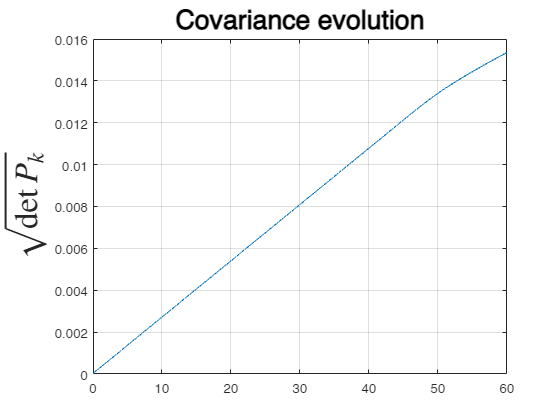


for i=1:3001;
    a(i)=sqrt(det(Pk(:,:,i)));
end
figure
plot((0:0.02:60), a)
title ('Covariance evolution',"FontSize",20)
ylabel('$\sqrt {\det {P_k}}$','Interpreter',"latex","FontSize",25)
grid on

**c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base**

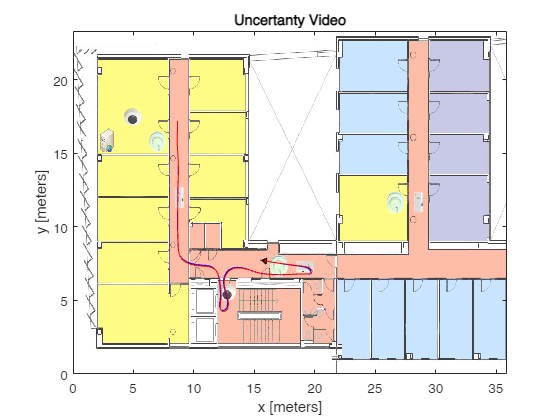

Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';
Triangle = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];

video = VideoWriter('2c_uncertanty_triangle.avi');
video.FrameRate = 45;
video.Quality = 100;
open(video);

image(I,'XData',x_img,'YData',y_img,"AlphaData",0.75);
axis xy
hold on
plot(Position(1,2:end), Position(2,2:end), 'b');
title('Uncertanty Video'); xlabel ('x [meters]'); ylabel ('y [meters]')
plot(Position_noise(1,2:end), Position_noise(2,2:end), 'r');
speed = 5;
r_patch=[];
t_patch=[];
max = 0;
for i=1:(length(t)-1)
    value = det(Pk(1:2, 1:2, i));
    if value > max
        max = value;
    end
end

for i=2:(length(t)-1)
        k_m=mod(i,speed);
        if k_m==0
            
            delete(r_patch);
            delete(t_patch);

            Triangle_uncertancy = Triangle;

            e = Pk(:, :, i);
            aux1 = Triangle_uncertancy(3, 2) * det(e(1:2, 1:2));
            aux2 = Triangle_uncertancy(1, 2) * det(e(1:2, 1:2));
            Triangle_uncertancy(3, 2) = aux1;
            Triangle_uncertancy(1, 2) = aux2;


            Robot_pose=transl(Position_noise(1,i),Position_noise(2,i),0)*trotz(Orientation_n(i));
            Robot_tr=Robot_pose*Robot; % moving the robot 
            triangle_tr=Robot_pose*transl(0.5,0,0)*trotz(pi)*Triangle_uncertancy';
            axis([0 35.9 0 23.31]);

            r_patch = patch(Robot_tr(1,:), Robot_tr(2,:),'red');
            t_patch = patch(triangle_tr(1,:), triangle_tr(2,:), 'yellow','FaceAlpha',.80);
            %pause(0.01);
            
            frame=getframe(gcf);
            writeVideo(video,frame);
        end
end
hold off

close(video);

## Mapping (10%)

Make a movie of laser data in Robot reference frame. See the video  of ATENEA: [Movie of the Laser Data seen in Robot Reference FrameURL](https://atenea.upc.edu/mod/url/view.php?id=3257292)

Make a video of laser data in Wordl Reference frame. Use here the code of the last TODO Lab about laser data. 

Display laser data every 2.5 m and erasing the previous walls after 200ms for better understanding.

See the video: '3_mapping.mp4' for inspiration

## Occupancy grid (30%)

Use Breshehan algorithm to build the map. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Use the idea behind the line tracing: Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

See: Mapping.mlx and '4_occupancy.mp4' for inspiration

% Add your code here

## Driving the Robot (20%)

Based on what you learn in motion arquitectures use the Goint2point for driving the robot. Use 'frontend.m' function to introduce way points such to recreate a trajectory similar to the past section.

Make a video displaying both trajectories: estimated and theoric. Add the ellipses to visualize uncertanty.

Notice that in this exercise the trajectories appear as the robot moves.

% Add your code here

## Localization (30%)

While driving the Robot in the last section Localize the Robot  by using the Similarity Transform. 

Visit again the folder 11_Localization for inspiration.

### Land Marks

Use the given Land Marks. They are known. They can be extracter from laser data, there are easy algorithms for finding they, like corner detection, etc ...

Lmk= [7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1];

### Plot Land Marks 

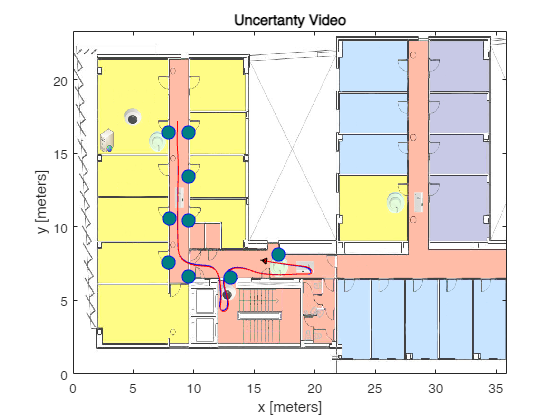

hold on
sz = 100;
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];

### Correct the noisy trajectory. 

Pay attention to the relationship of the variables

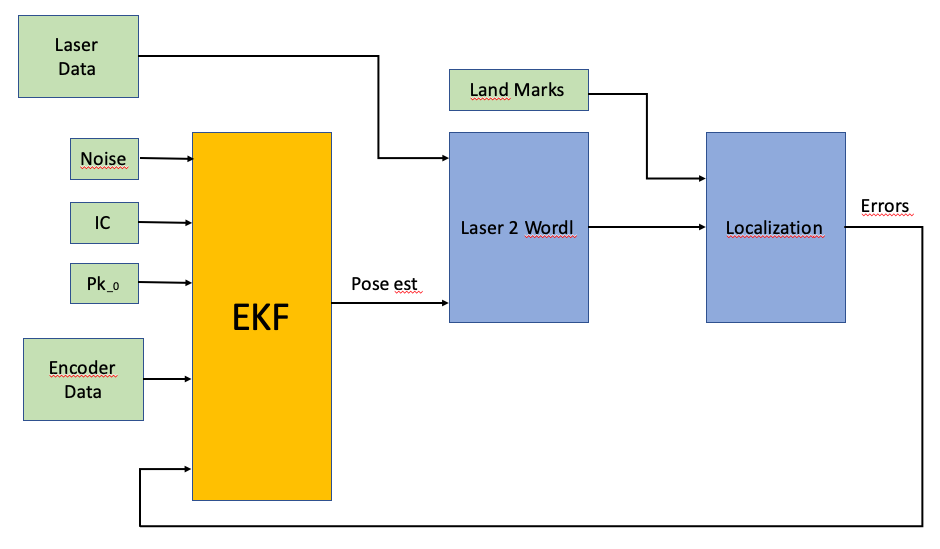

Update the estimated covarianze matrix by the sensor, knowing that the Laser scanner has and acuraccy 4 mm with a standard deviation of 0.2 mm.

1.- Display in a figure: the map, theoric trajectory (no noise) and the corrected trajectory. See: Expected_Localization.mp4

2.- Make a 'log' with the following columns:  estimated noisy pose, corrected position, number of Land-marks seen,  and the errors and the covariance matrix Pk.

% Add your code here